# Avances ASK

Gallegos Ruiz Diana Abigail

25/04/2022

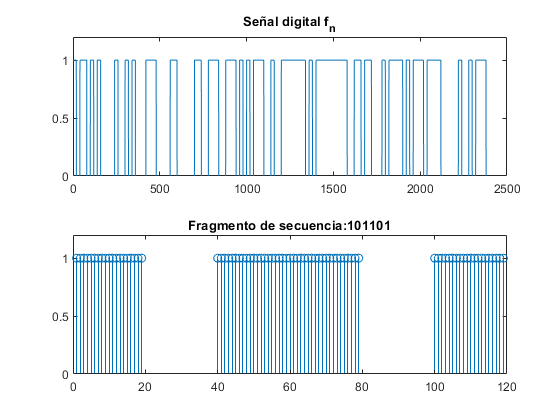

clc
close all
clear all

% -------------- SECUENCIA DE BITS - ----------
num = randperm(255,15);
numb=cellstr(dec2bin(num));
for i=1:15 %Concatenar secuencia de bits
    if i==1 || i==2
        vec=strcat(numb(1),numb(2));
    else
        vec= strcat(vec,numb(i));
    end    
end

vec=char(vec);

%-------GRÁFICA DE LA SECUENCIA GENERADA  -------------------

k=length(vec)*20;
fdn=zeros(1,k);

for i=1:length(vec)
n=20*i;
        if vec(i) == '0' % Mandará un pulso de amplitud 0.5
          for j=n-20:n
              if (j==0)
                  fdn(1)=-1;
              else
                  fdn(j)=-1;
              end
          end
        else % Mandará un 1
          for j=n-20:n
             if (j==0)
                  fdn(1)=1;
              else
                  fdn(j)=1;
              end
          end
        end
 end

figure(1)
tiledlayout(2,1)
nexttile
plot(fdn)
ylim([0,1.2])
title('Señal digital f_n')
nexttile
stem(fdn)
xlim([0,120])
ylim([0,1.2])
title(strcat('Fragmento de secuencia: ',vec(1,1:6)))

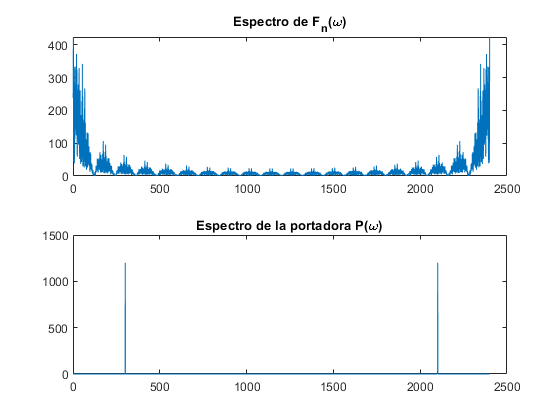



% %----------- ESPECTROS -----------------
% 
n=1:k;
p=cos(2*pi*n/8);
FW=fft(fdn);
PW=fft(p);
figure(2)
tiledlayout(2,1)
nexttile
plot(abs(FW));
title('Espectro de F_n(\omega)')
nexttile
plot(abs(PW))
title('Espectro de la portadora P(\omega)')

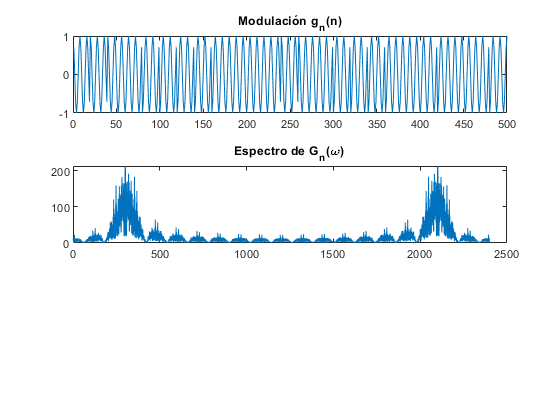


%------------ MODULACIÓN ------------------

y=p.*fdn;
figure(3)
tiledlayout(3,1)
 nexttile
plot(y)
ylim([0.4,1.1])
title('Modulación g_n(n)')
plot(y)
xlim([0,300])
title('Modulación g_n(n)')
GN=fftn(y);
nexttile
plot(abs(GN))
title('Espectro de G_n(\omega)')

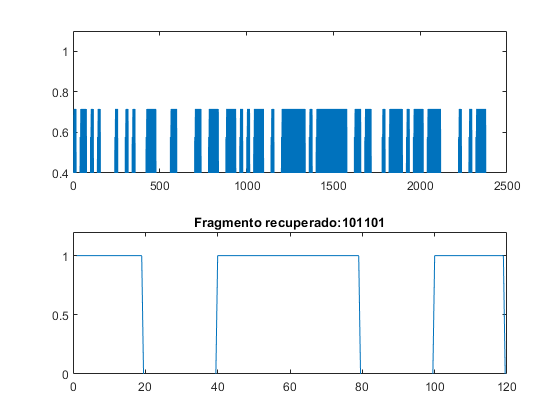


% %------------------- DEMODULACIÓN Y FILTRADO  -------------

dy=y.*p;
wc=1/3;
[N,D] = butter(1,0.333,'low');
fdnrec=filter(N,D,dy);
figure(4)
nexttile
plot(fdnrec)
ylim([0.4,1.1])
nexttile
plot(fdn)
xlim([0,120])
ylim([0,1.2])
title(strcat('Fragmento recuperado: ',vec(1,1:6)))